# Swing by Venus - Numerik Abschlussprojekt

Urs Müller, Joachim Spitaler, Leonie Graf

**1) Sonnensystem**

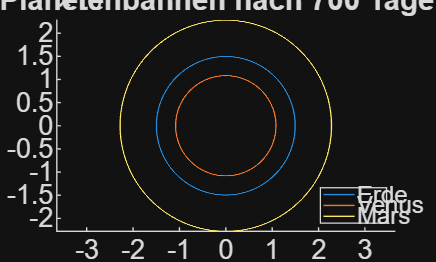

clear all, close all, clc, clf  

tspan = linspace(0,700,100000);
phi0M = -1.70;

Earth = posEarth(tspan);
Venus = posVenus(tspan);
Mars = posMars(tspan, phi0M);

figure;
hold on;
plot(Earth(:,1), Earth(:,2));
plot(Venus(:,1), Venus(:,2));
plot(Mars(:,1), Mars(:,2));
axis equal;
legend({"Erde", "Venus", "Mars"}, 'Location', 'southeast')
title("Planetenbahnen nach " + num2str(max(tspan)) + " Tagen")

**2) Gravitationsfeld **

%Startposition der Venus abgreifen
rV = posVenus(0)';
dmin = 1e5;
dmax = 1e12;

f = @(d) venus_ratio(d,phi0M,rV);
dsolve = fzero(f,[dmin;dmax]);
fprintf("Abstand zu Venus bei 0.01 der Gravitation = %.1f km",dsolve/1000)

Abstand zu Venus bei 0.01 der Gravitation = 1693196.3 km

**3) Bahnkurve einer Sonde in 1 Jahr (365.25 Tage)**

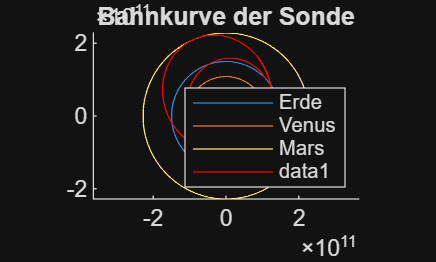

v0 = 13.333 * 10^3 * 86400; %Startgeschwindigkeit, Meter/Tage
angle = -1.61172074;
options = odeset("AbsTol",1e-10, "RelTol",1e-8, "MaxStep", 0.01);
%Toleranz eventuell als Vektor übergeben

% Funktion addiert Erdgeschwindigkeit, richtet nach Winkel aus
[pos, v0_vec] = v0_calc(v0, angle);
[t, y] = ode113(@(t,y) grav_calc(t,y,phi0M), tspan, [pos'; v0_vec], options);
plot(y(:,1), y(:,2), "r-");
hold on;

[t_sun, y_sun] = ode45(@grav_sun, tspan, [pos'; v0_vec], options);
%plot(y_sun(:,1), y(:,2));

%legend({"Erde", "Venus", "Mars", "Sonde"}, 'Location','southeast')
title("Bahnkurve der Sonde")


rS = y(:,1:2);              % Satellit
rV = posVenus(t);           

d = vecnorm(rV - rS, 2, 2);  % euklidische Distanz je Zeitpunkt
distMin = min(d);

fprintf("Minimale Distanz zu Venus: %.2f", distMin/1000)

Minimale Distanz zu Venus: 12556.26


speed = vecnorm(y(:,3:4),2,2);
figure;
hold off;
plot(t, speed)
title("Geschwindigkeit Sonde über Zeit")

**4) Trajektorie**

v0 = 13.333 * 10^3 * 86400;     %Startgeschwindigkeit, Meter/Tage
target_dist = 12300 * 10^3;     % 20.000 km in Metern

%Eingrenzung der Startwerte
test_angles = linspace(0, -1.8, 36);
test_diffs = zeros(size(test_angles));

for i = 1:length(test_diffs)
    test_diffs(i) = flybyV_dist(test_angles(i), v0, phi0M, target_dist);
end

[mindis, idx] = min(test_diffs);
test_angles(idx)

ans = -1.5943


objective_min = @(a) (flybyV_dist(a, v0, phi0M, target_dist))^2;

start_angle = -1.6; %Startwert
best_angle = fminsearch(objective_min, start_angle);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 2012.816413 



fprintf('Optimaler Winkel: %.8f rad\n', best_angle);

Optimaler Winkel: -1.61172074 rad


**5) Mars **

objective_min = @(phi) (flybyM_dist(phi, angle, v0))^2;
start_phi = -0.5; %Startwert
best_phi = fminsearch(objective_min, start_phi);


[~, min_dist, flyby_t] = flybyM_dist(best_phi, angle, v0);

fprintf("Optimaler Startwinkel Mars: %.2f rad", best_phi);
fprintf("Minimaler Abstand: %.0f km", min_dist/1000);
fprintf("Flyby-Zeitpunkt: %.2f Tage", flyby_t);

Ergebnisse darstellen

% Simulation bis zum Mars-Treffzeitpunkt
tspan = [0 flyby_t];

[pos0, v0_vec] = v0_calc(v0, best_angle);
y0 = [pos0(:); v0_vec(:)];

options = odeset('AbsTol',1e-14,'RelTol',1e-12);

[t, y] = ode113(@(t,y) grav_calc(t,y,best_phi), tspan, y0, options);

rS = y(:,1:2);                 % Sonde
rE = posEarth(t);
rV = posVenus(t);
rM = posMars(t, best_phi);

%Kreibahnen Planeten
tt = linspace(0, max(t), 500);
bE = posEarth(tt);
bV = posVenus(tt);
bM = posMars(tt, best_phi);

figure
hold on
axis equal
grid on

% Bahnen (gestrichelt)
plot(bE(:,1), bE(:,2), 'b--')
plot(bV(:,1), bV(:,2), 'g--')
plot(bM(:,1), bM(:,2), 'r--')

% Sonne
Rsun = 7e9;   % nur optisch!
theta = linspace(0,2*pi,50);
fill(Rsun*cos(theta), Rsun*sin(theta), 'y', 'EdgeColor','none')

% Animierte Objekte (Startwerte)
hE = plot(rE(1,1), rE(1,2), 'bo', 'MarkerFaceColor','b');
hV = plot(rV(1,1), rV(1,2), 'go', 'MarkerFaceColor','g');
hM = plot(rM(1,1), rM(1,2), 'ro', 'MarkerFaceColor','r');
hS = plot(rS(1,1), rS(1,2), 'ko', 'MarkerFaceColor','k');

% Spur der Sonde
hTrail = plot(rS(1,1), rS(1,2), 'k-');

xlabel('x [m]')
ylabel('y [m]')
title('Venus Swingby → Mars Transfer')

N = length(t);
skip = max(1, floor(N/800));   % Geschwindigkeit

for k = 1:skip:N

    set(hE, 'XData', rE(k,1), 'YData', rE(k,2))
    set(hV, 'XData', rV(k,1), 'YData', rV(k,2))
    set(hM, 'XData', rM(k,1), 'YData', rM(k,2))
    set(hS, 'XData', rS(k,1), 'YData', rS(k,2))

    set(hTrail, 'XData', rS(1:k,1), 'YData', rS(1:k,2))

    drawnow
end


